microstep = 8;
driveVoltage = 48;

PID

p = 09.228;
i = 0.2;
d = 0.098222264;
speedLimit = 300

speedLimit = 300

errorDeadZone = .0

errorDeadZone = 0

Input

rocketPosTable = readtable("L1PositionOverTime.csv");
rocketPos = [rocketPosTable.Var3,rocketPosTable.Var4,rocketPosTable.Var2];
rotatorPos = [30 0 0];
direction = rocketPos-rotatorPos;
pro = [direction(:,1),direction(:,2),direction(:,3).*0];
elevation = [];
for i = 1:1:length(direction)
    elevation = [elevation acosd(dot(pro(i,:),direction(i,:))/(norm(pro(i,:))*norm(direction(i,:))))];
end
angleReqFast = timeseries(elevation',rocketPosTable.Var1);
angleReq = angleReqFast

  timeseries

  Common Properties:
            Name: 'unnamed'
            Time: [1067x1 double]
        TimeInfo: [1x1 tsdata.timemetadata]
            Data: [1067x1 double]
        DataInfo: 

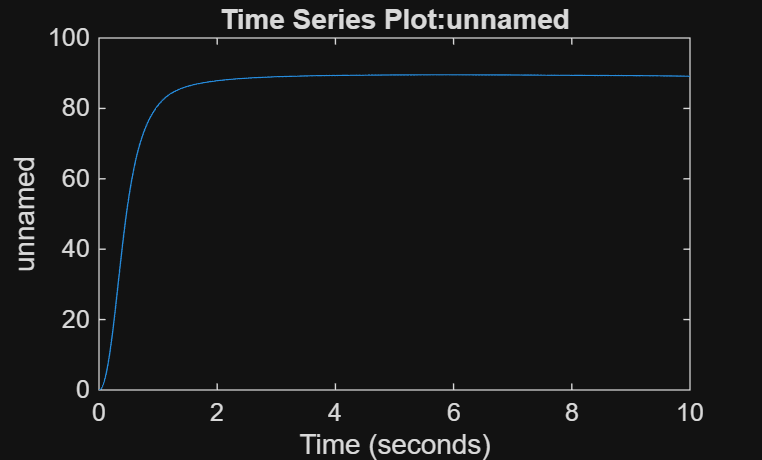

% angleReq = resample(resample(angleReqFast,[0:0.25:10],'zoh'),rocketPosTable.Var1,'zoh')
plot(angleReq)

Outputs

stepperModel = sim("FreakMotor.slx");

Found algebraic loop that contains: 
FreakMotor/Solver Configuration/EVAL_KEY/STATE_1
FreakMotor/Solver Configuration/EVAL_KEY/OUTPUT_1_0
FreakMotor/Sum
FreakMotor/Dead Zone (discontinuity)
FreakMotor/Gain1
FreakMotor/PID Controller/Parallel P Gain/Internal Parameters/Proportional Gain
F

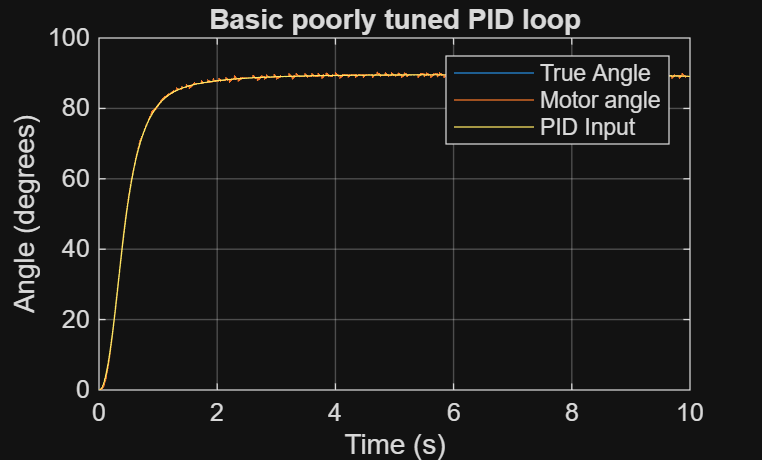

plot(angleReqFast)
hold on
plot(theta)
plot(angleReq)
legend("True Angle", "Motor angle","PID Input");
xlabel("Time (s)");
ylabel("Angle (degrees)");
grid on
title("Basic poorly tuned PID loop")
xlim([0 10])
hold off

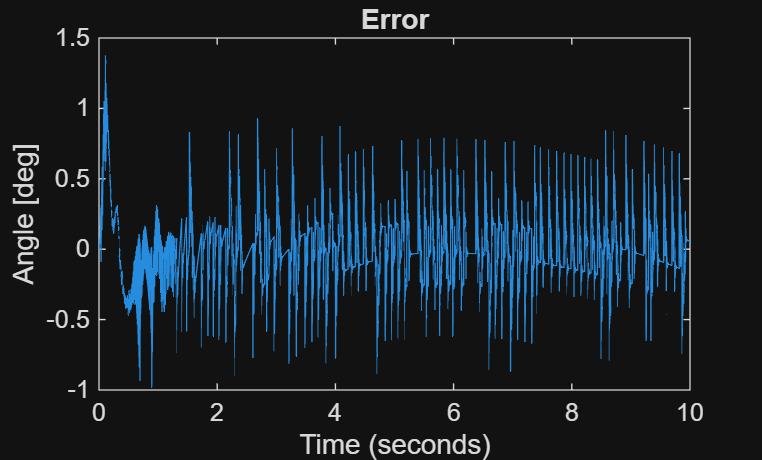


plot(error)
hold on
ylabel("Angle [deg]")
title("Error")
hold off

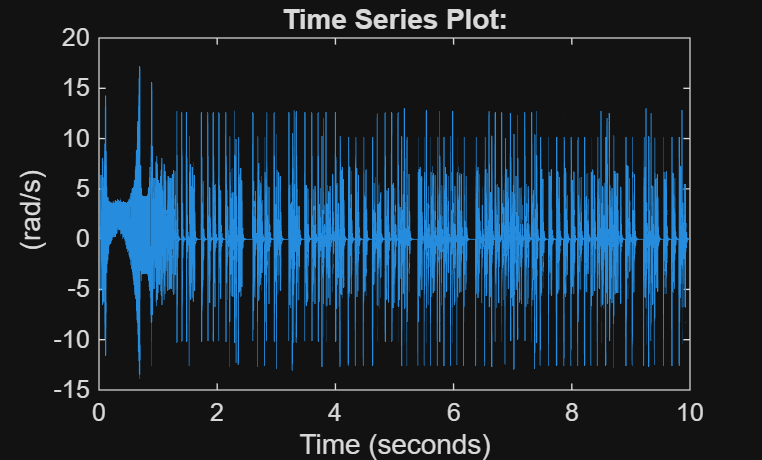


plot(thetadot)